clear all 
clc

% Question 1:

%part I :
N=1000

N = 1000

Fs = 16000

Fs = 16000

g = 0.5

g = 0.5000


input_voice = audioread("Echo_System_Test_Input.m4a")

input_voice =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


%play(input_voice)
figure
subplot(2,1,1)
plot(input_voice)
title('Input Voice - (Time-Domain)')
input_voice_spectrum = real(fftshift(fft(input_voice)))

input_voice_spectrum =    -0.0044   -0.0050
    0.0055    0.0050
    0.0009    0.0004
    0.0025    0.0020
   -0.0006   -0.0009
    0.0027    0.0024
    0.0011    0.0010
    0.0013    0.0012
   -0.0025   -0.0025
    0.0043    0.0043


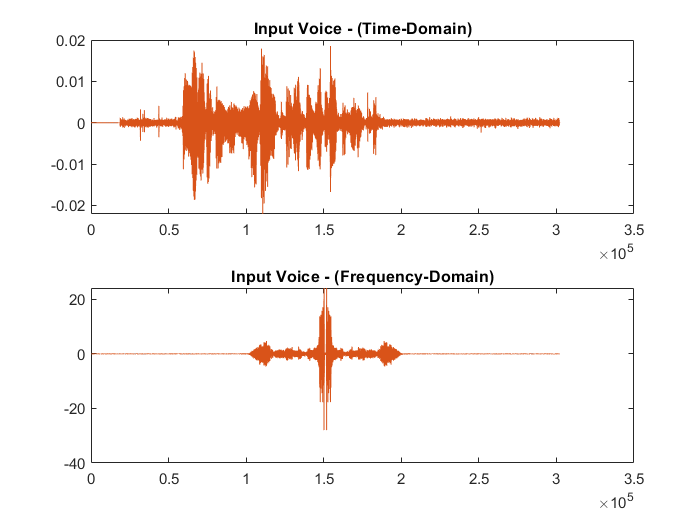


subplot(2,1,2)
plot(input_voice_spectrum)
title('Input Voice - (Frequency-Domain)')



[input_voice,Fs] = audioread("Echo_System_Test_Input.m4a")

input_voice =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


Fs = 48000

%play(input_voice)

figure
subplot(2,1,1)
plot(input_voice,'Color', '#B3B2B2')
title('Input Voice - Fs: 16kHz (Time-Domain)')
input_voice_spectrum = real(fftshift(fft(input_voice)))

input_voice_spectrum =    -0.0044   -0.0050
    0.0055    0.0050
    0.0009    0.0004
    0.0025    0.0020
   -0.0006   -0.0009
    0.0027    0.0024
    0.0011    0.0010
    0.0013    0.0012
   -0.0025   -0.0025
    0.0043    0.0043


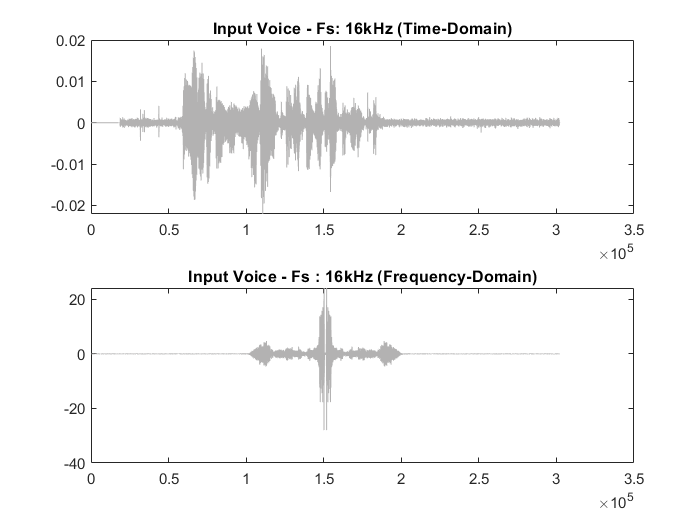


subplot(2,1,2)
plot(input_voice_spectrum,'Color', '#B3B2B2')
title('Input Voice - Fs : 16kHz (Frequency-Domain)')

    
% Sampling Frequency '16 kHz' isnt enough for our input voice
% Resampling with '48 kHz':
Fs = 48000

Fs = 48000

[input_voice,Fs] = audioread("Echo_System_Test_Input.m4a")

input_voice =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


Fs = 48000

figure

subplot(2,1,1)
plot(input_voice,'Color', '#595959')
title('Input Voice - Fs: 48kHz (Time-Domain)')
input_voice_spectrum = real(fftshift(fft(input_voice)))

input_voice_spectrum =    -0.0044   -0.0050
    0.0055    0.0050
    0.0009    0.0004
    0.0025    0.0020
   -0.0006   -0.0009
    0.0027    0.0024
    0.0011    0.0010
    0.0013    0.0012
   -0.0025   -0.0025
    0.0043    0.0043


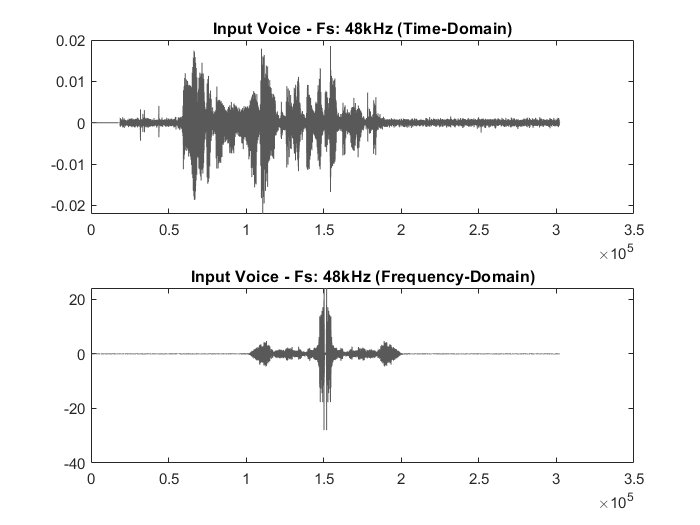


subplot(2,1,2)
plot(input_voice_spectrum,'Color', '#595959')
title('Input Voice - Fs: 48kHz (Frequency-Domain)')


output = apply_echo(input_voice,g,N,Fs)

N = 1000

g = 0.5000

Fs = 48000

num =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


echo =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


output =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


out = audioplayer(output,Fs)

out =   audioplayer with properties:

       SampleRate: 48000
    BitsPerSample: 16
      NumChannels: 2
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 302079
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


%play(out)

figure

subplot(2,1,1)
plot(output,'Color','#7B67A3')
title('Echo Voice (Gain = 0.5) - Fs: 48kHz (Time-Domain)')
audiowrite("Echo_Gain_0.5.wav",output,Fs)

output_spectrum = real(fftshift(fft(output)))

output_spectrum =    -0.0135   -0.0152
    0.0172    0.0156
    0.0022    0.0008
    0.0082    0.0071
   -0.0045   -0.0054
    0.0092    0.0086
    0.0031    0.0028
    0.0014    0.0014
   -0.0051   -0.0049
    0.0099    0.0102


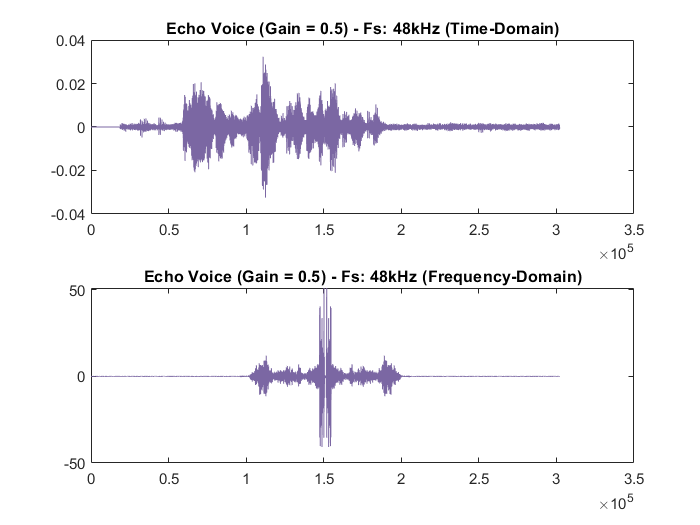

subplot(2,1,2)
plot(output_spectrum,'Color','#7B67A3')
title('Echo Voice (Gain = 0.5) - Fs: 48kHz (Frequency-Domain)')




% part II: 
% we can increase the gain by 0.1 steps from 0.5 to 1:
g = 0.6

g = 0.6000


output = apply_echo(input_voice,g,N,Fs)

N = 1000

g = 0.6000

Fs = 48000

num =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


echo =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


output =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


out = audioplayer(output,Fs)

out =   audioplayer with properties:

       SampleRate: 48000
    BitsPerSample: 16
      NumChannels: 2
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 302079
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


%play(out)

figure

subplot(2,1,1)
plot(output,'Color','#3670E0')
title('Echo Voice (Gain = 0.6) - Fs: 48kHz (Frequency-Domain)')
audiowrite("Echo_Gain_0.6.wav",output,Fs)

output_spectrum = real(fftshift(fft(output)))

output_spectrum =    -0.0159   -0.0178
    0.0202    0.0184
    0.0024    0.0008
    0.0098    0.0085
   -0.0063   -0.0073
    0.0110    0.0104
    0.0034    0.0032
    0.0007    0.0008
   -0.0050   -0.0047
    0.0102    0.0107


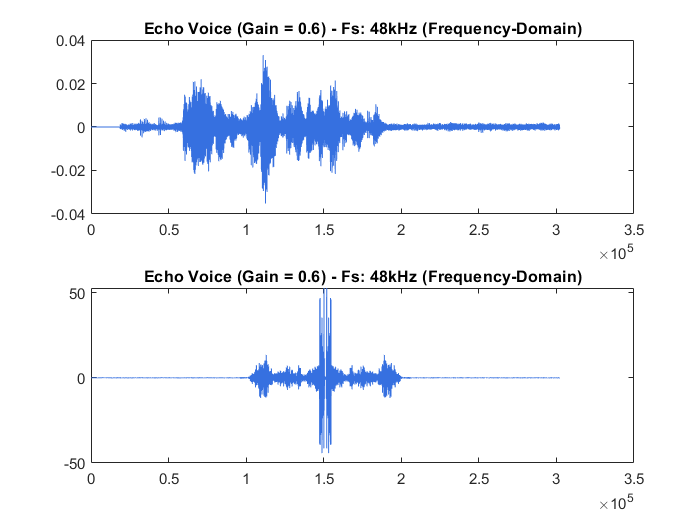

subplot(2,1,2)
plot(output_spectrum,'Color','#3670E0')
title('Echo Voice (Gain = 0.6) - Fs: 48kHz (Frequency-Domain)')



g = 0.7

g = 0.7000


output = apply_echo(input_voice,g,N,Fs)

N = 1000

g = 0.7000

Fs = 48000

num =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


echo =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


output =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


out = audioplayer(output,Fs)

out =   audioplayer with properties:

       SampleRate: 48000
    BitsPerSample: 16
      NumChannels: 2
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 302079
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


%play(out)

figure

subplot(2,1,1)
plot(output,'Color','#36BAE0')
title('Echo Voice (Gain = 0.7) - Fs: 48kHz (Frequency-Domain)')
audiowrite("Echo_Gain_0.7.wav",output,Fs)

output_spectrum = real(fftshift(fft(output)))

output_spectrum =    -0.0198   -0.0222
    0.0255    0.0232
    0.0026    0.0007
    0.0126    0.0111
   -0.0099   -0.0109
    0.0141    0.0135
    0.0038    0.0037
   -0.0008   -0.0006
   -0.0044   -0.0039
    0.0100    0.0106


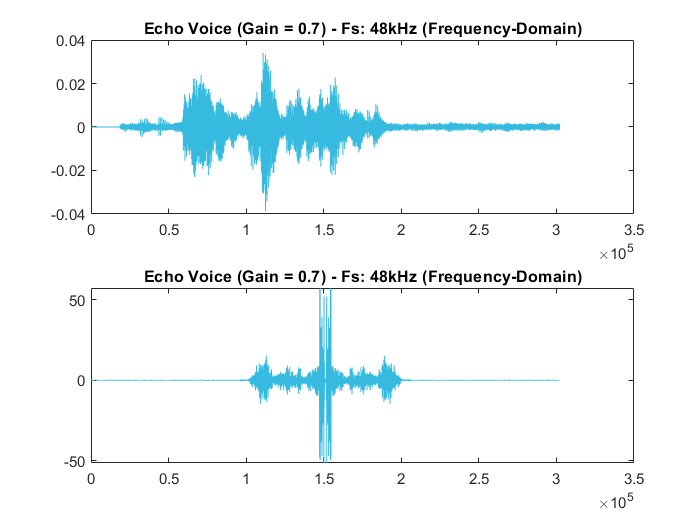

subplot(2,1,2)
plot(output_spectrum,'Color','#36BAE0')
title('Echo Voice (Gain = 0.7) - Fs: 48kHz (Frequency-Domain)')





g = 0.8

g = 0.8000


output = apply_echo(input_voice,g,N,Fs)

N = 1000

g = 0.8000

Fs = 48000

num =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


echo =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


output =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


out = audioplayer(output,Fs)

out =   audioplayer with properties:

       SampleRate: 48000
    BitsPerSample: 16
      NumChannels: 2
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 302079
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


%play(out)

figure

subplot(2,1,1)
plot(output,'Color','#E2C721')
title('Echo Voice (Gain = 0.8) - Fs: 48kHz (Frequency-Domain)')
audiowrite("Echo_Gain_0.8.wav",output,Fs)

output_spectrum = real(fftshift(fft(output)))

output_spectrum =    -0.0279   -0.0312
    0.0364    0.0334
    0.0027    0.0003
    0.0185    0.0167
   -0.0184   -0.0195
    0.0199    0.0196
    0.0041    0.0044
   -0.0046   -0.0039
   -0.0018   -0.0010
    0.0078    0.0087


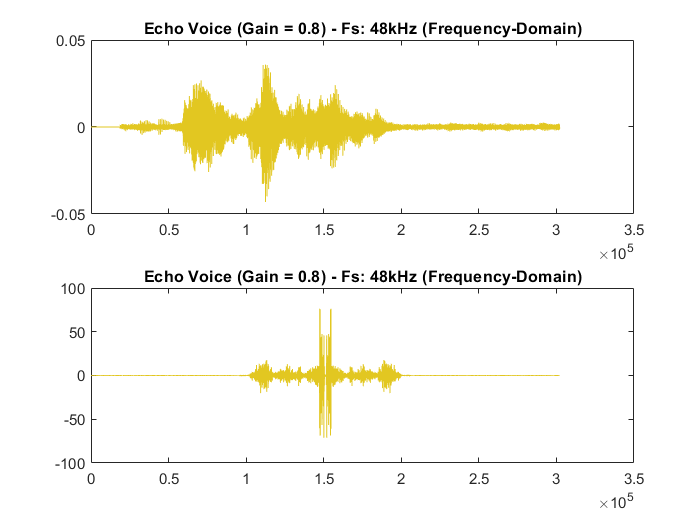

subplot(2,1,2)
plot(output_spectrum,'Color','#E2C721')
title('Echo Voice (Gain = 0.8) - Fs: 48kHz (Frequency-Domain)')




g = 0.9 

g = 0.9000


output = apply_echo(input_voice,g,N,Fs)

N = 1000

g = 0.9000

Fs = 48000

num =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


echo =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


output =          0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


out = audioplayer(output,Fs)

out =   audioplayer with properties:

       SampleRate: 48000
    BitsPerSample: 16
      NumChannels: 2
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 302079
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


%play(out)

figure

subplot(2,1,1)
plot(output,'Color','#ECA539')
title('Echo Voice (Gain = 0.9) - Fs: 48kHz (Frequency-Domain)')
audiowrite("Echo_Gain_0.9.wav",output,Fs)

output_spectrum = real(fftshift(fft(output)))

output_spectrum = 10×2
   -0.0523   -0.0583
    0.0718    0.0668
    0.0014   -0.0019
    0.0346    0.0329
   -0.0435   -0.0438
    0.0311    0.0318
    0.0036    0.0048
   -0.0132   -0.0116
    0.0055    0.0071
    0.0007    0.0021


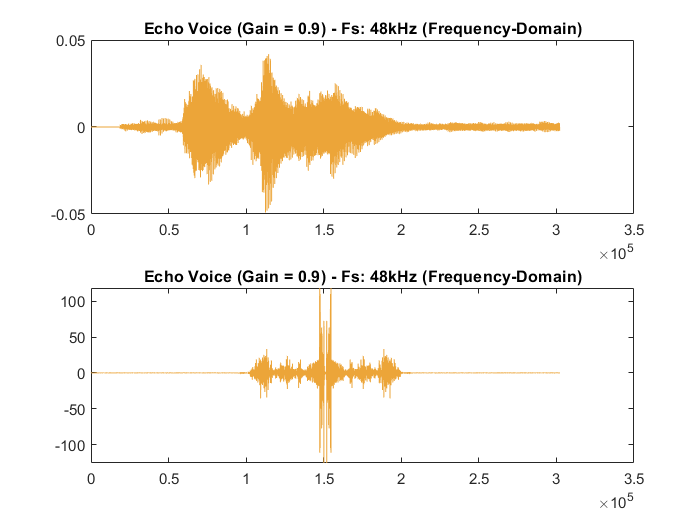

subplot(2,1,2)
plot(output_spectrum,'Color','#ECA539')
title('Echo Voice (Gain = 0.9) - Fs: 48kHz (Frequency-Domain)')




g = 1

g = 1


output = apply_echo(input_voice,g,N,Fs)

N = 1000

g = 1

Fs = 48000

num = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den = 1×30
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num = 1×30
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den = 1×30
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


num = 1×30
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


den = 1×30
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


echo = 10×2
         0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


output = 10×2
         0    0.0000
         0    0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0    0.0000
         0   -0.0000
         0   -0.0000
         0   -0.0000


out = audioplayer(output,Fs)

out =   audioplayer with properties:

       SampleRate: 48000
    BitsPerSample: 16
      NumChannels: 2
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 302079
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


%play(out)

figure

subplot(2,1,1)
plot(output,'Color','#C12D19')
title('Echo Voice (Gain = 1) - Fs: 48kHz (Frequency-Domain)')
audiowrite("Echo_Gain_1.wav",output,Fs)

output_spectrum = real(fftshift(fft(output)))

output_spectrum = 10×2
    0.0444    0.0488
    0.2431    0.2475
    0.0086    0.0128
    0.0747    0.0786
   -0.0557   -0.0521
    0.0542    0.0573
    0.0220    0.0248
    0.0001    0.0024
    0.0379    0.0398
    0.0116    0.0131


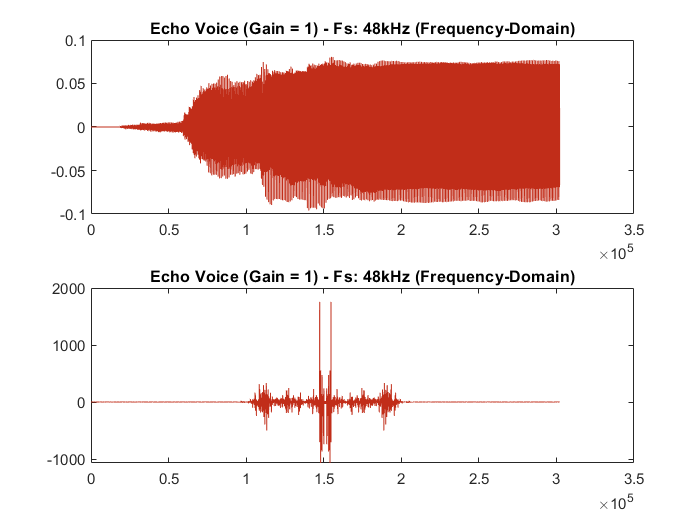

subplot(2,1,2)
plot(output_spectrum,'Color','#C12D19')
title('Echo Voice (Gain = 1) - Fs: 48kHz (Frequency-Domain)')

function echo = apply_echo(voice,gain,delay_offset,sample_rate)
        
    % designing echo transfer function with gain = 0.5, N(Delay = 1000)
    N = delay_offset
    g = gain
    Fs = sample_rate
    
    num = zeros(1,N+1)
    den = zeros(1,N+1)
    
    num(1,1) = 1
    den(1,1) = 1
    num(1,N+1) = 1-g
    den(1,N+1) = -g
 
    echo = filter(num,den,voice)
    return
end